clc; close all;
clear all; close all; clc;

**Import LUT from Textfile**

The following code is used to read the hexadecimal values out of the textfilte LUT_full.txt. The values are converted to decimal values. To apply the twos complement, a shift of 4294967296 is applied.

% Open the file for reading
fileID = fopen("LUT_full.txt", 'r');
% Read the file contents into a cell array
hexValues = textscan(fileID, '%s');
% Close the file
fclose(fileID);
% Convert the cell array to a regular array of strings
hexValues = hexValues{1};
% Initialize a vector to hold the decimal values
decimalValues_LUT = zeros(length(hexValues), 1);
% Convert each hexadecimal string to a decimal value
for i = 1:length(hexValues)
    % Remove the '0x' prefix and convert to decimal
    decimalValues_LUT(i) = hex2dec(hexValues{i}(3:end-1));
end
for i = 2050:length(hexValues)
    decimalValues_LUT(i) = decimalValues_LUT(i)-4294967296;
end

**Phase Accumulator**

The Phase Accumulator is implemented, using a for loop. The modulo operation is needed, when applying a phase shift. Then the table can be read multiple times. The fix operation is similar to a cast operation. **The FTW can be a value greater or smaller 1 to apply fractional and integer bits.**

FTW = 0.5;%Applies fractional and integer bits
N_LUT = length(decimalValues_LUT);
N_iterate = N_LUT/FTW;
output_vector = zeros(1,N_iterate);
accumulator = 504;%Phase offset
for i=1:N_iterate
    result = mod(FTW + accumulator, N_LUT+1);
    accumulator = result;
    output_vector(i) = fix(result);
end

**Plot the Sawtooth output**

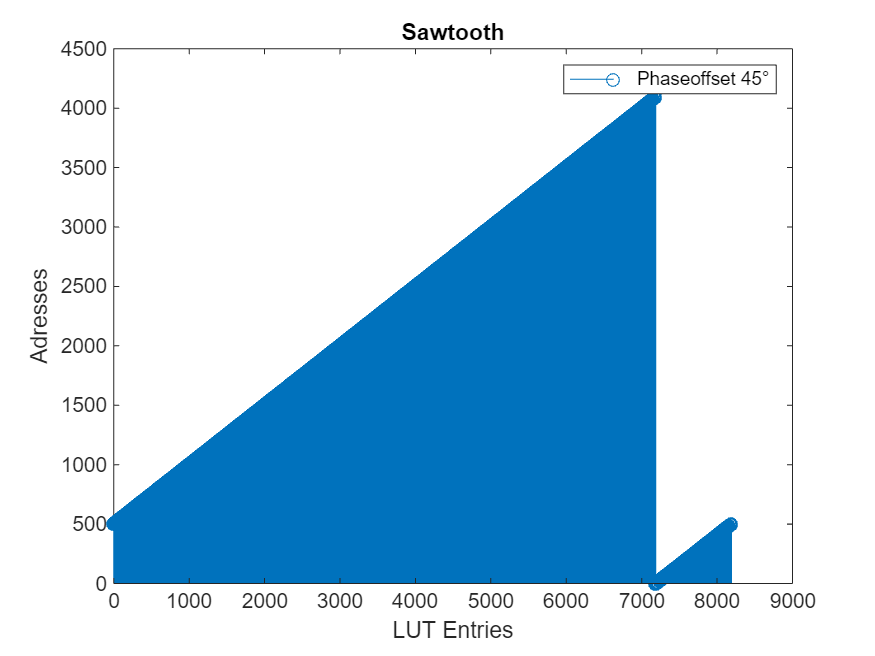

figure
stem(output_vector);
legend('Phaseoffset 45°')
title('Sawtooth')
xlabel('LUT Entries');
ylabel('Adresses');

**Read out the LookUpTable**

Matlab cannot use index 0. Hence, we start from $\frac{1}{\textrm{FTW}}$. If an Phase offset is applied, index 0 is skipped by the if condition.

sine = zeros(1,length(output_vector));
start = 1;
%Index Anpassung da für FTW < 1 output_vector mit nullen beginnt 
if FTW < 1
    start = 1/FTW;
end
for i = start:length(output_vector)
    k = output_vector(i);
    if(k == 0)
        k = 1;
    end
    sine(i) = decimalValues_LUT(k);
end

**Plot the Sinweave over Sampling frequency**


$$f_v =\frac{\left(\textrm{FTW}*\textrm{fs}\right)}{2^n }$$
  
$$2^{n\;} :=\textrm{Number}\;\textrm{of}\;\textrm{LUT}\;\textrm{entries}$$


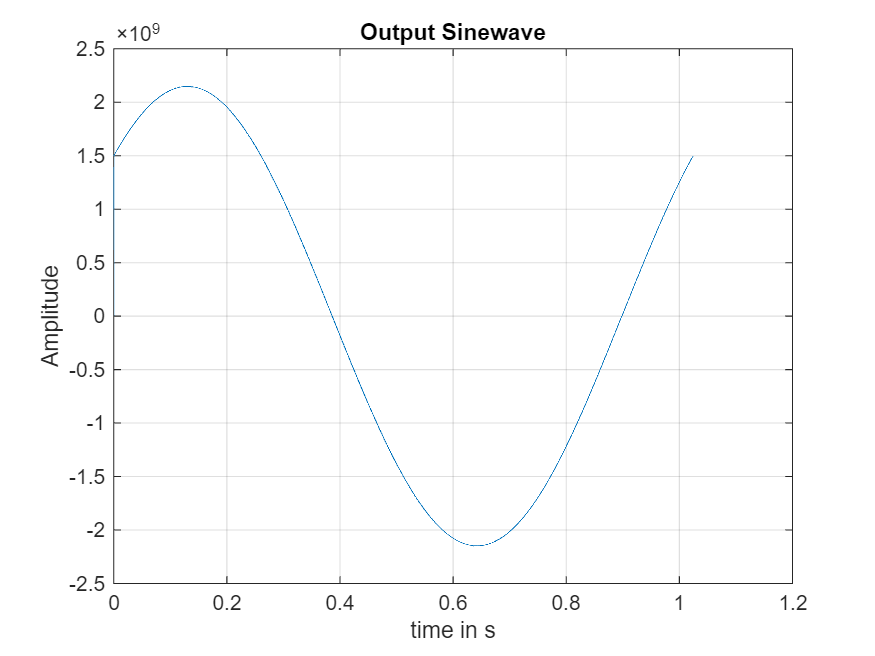

figure
fs = 8000;
Ts=1/fs;
T=1/FTW*N_LUT*Ts-Ts;
t = 0:Ts:T;
plot(t,sine);
title('Output Sinewave')
xlabel('time in s');
ylabel('Amplitude');
grid on;

**Explanations:**

The formula provided is used for subsequent calculations.

The calculated frequency tuning word (FTW) for iii is 61.44. Applying an FTW of 61 results in a frequency of 2.38 MHz. For a 12-bit configuration, an FTW of 983.04 is calculated. Applying an FTW of 983 yields an output frequency of 2.3999 MHz.

**Conclusion:** 

Increasing the number of bits for the phase accumulator not only enables higher frequencies but also enhances precision.